# T-Maze Experiment


close all; clear; clc;

load(fullfile(get_behavior_root(),"DataTmaze.mat"));

pos = [4,7,8,9,11];
neg = [2,3,6,10];

animals = length(Data.animal);
arms = 3;
trial = length(Data.animal(1).trial);
entry = cell(1,arms);
entry(1:3) = {NaN(1,3)};
all_entries = cell(trial,animals);
distance_moved = nan(trial,animals);
completed = nan(trial,animals);

%Pilot; trial 5-51 training, 53-108 testing
%Experiment: 40 test trials, 80 files

for a = 1:animals
    trials = length(Data.animal(a).trial);
     
    for t = 1:trials
        if height(Data.animal(a).trial(t).name)<3
            continue
        else
        entries = table2array(Data.animal(a).trial(t).name(:,11:13));
        entries = fillmissing(entries,'next');
        time = table2array(Data.animal(a).trial(t).name(:,2));
        end_time = length(time);
 
        % deal with when - is read into string
        control = iscell(entries);
        if control == 1 
            buffer = strrep(entries, '-', 'NaN');
            make_double = cellfun(@(x) str2double(x),buffer);
            entries = make_double;
        end 
        
        all_entries{t,a} = entries;
        
        distance = table2array(Data.animal(a).trial(t).name(:,8));
        
        control2 = iscell(distance);
        if control2 == 1
            distance = cellfun(@(x) str2double(x),distance);
        end
        distance_moved(t,a) = sum(distance,'omitnan');
        
        pat = [0,1]; %gives index of the 0, not 1
        ent = arrayfun(@(x)strfind(entries(:,x)',pat),1:size(entries,2),'UniformOutput',false); 
        entry=cellfun(@(x) x+1,ent,'un',0); %adjusts the index
        
        % Finding the first entry of the goal arms 
        try
            arm1 = entry{1,1}(1,1);

        catch  %If an arm is empty set the time index to extremely high
            if isempty(arm1)
                arm1 = 1000000;
            end
        end
        
        try
            arm2 = entry{1,2}(1,1);
            
        catch 
            if isempty(arm2)
            arm2 = 1000000;
            end
        end
        [~,compl_arm] = min([arm1, arm2]); %when comparing now it will always be the smallest
        
        completed(t,a) = compl_arm;
        
        % Reset the arm values to something that will not get picked as first entry (in case it was empty)
        arm1 = 1000000; 
        arm2 = 1000000;
        
        sp = table2array(Data.animal(a).trial(t).name(:,9));
        
        control3 = iscell(sp);
        if control3 == 1
            sp = cellfun(@(x) str2double(x),sp);
        end
        speed(t,a) = mean(sp,'omitnan');

        end
    end
end


## Score Success

% PREPROCESS: Sometimes I had to delete training trials = not equal length, but test trials should be 
for p = 1:animals 
    [idx,~] = find(completed(:,p));
    new_vect = completed(idx,p);
    test_trials(:,p) = new_vect(end-79:end); % 80 test trials for experimental animals

end

% when animal has alternated = 1, when it did not = 0
score_m = score_mat(test_trials(:,1:end),animals,1);

% Average score over n number of trials (made function)
score_session = (average_matrix(score_m,animals,4)).*100;
score_day = (average_matrix(score_m,animals,8)).*100;


## Separate into genotypes

 
Table of the Barnard's exact test results for:
a = 28, b = 4, c = 25, d = 15
---------------------------------------------------
  Wald statistic     Nuisance parameter      P  
---------------------------------------------------
      2.3916               0.9701          0.0227
---------------------------------------------------
 
[Note:For a least conflict with figure, press the left mouse button on the legend and drag to the desired location.]


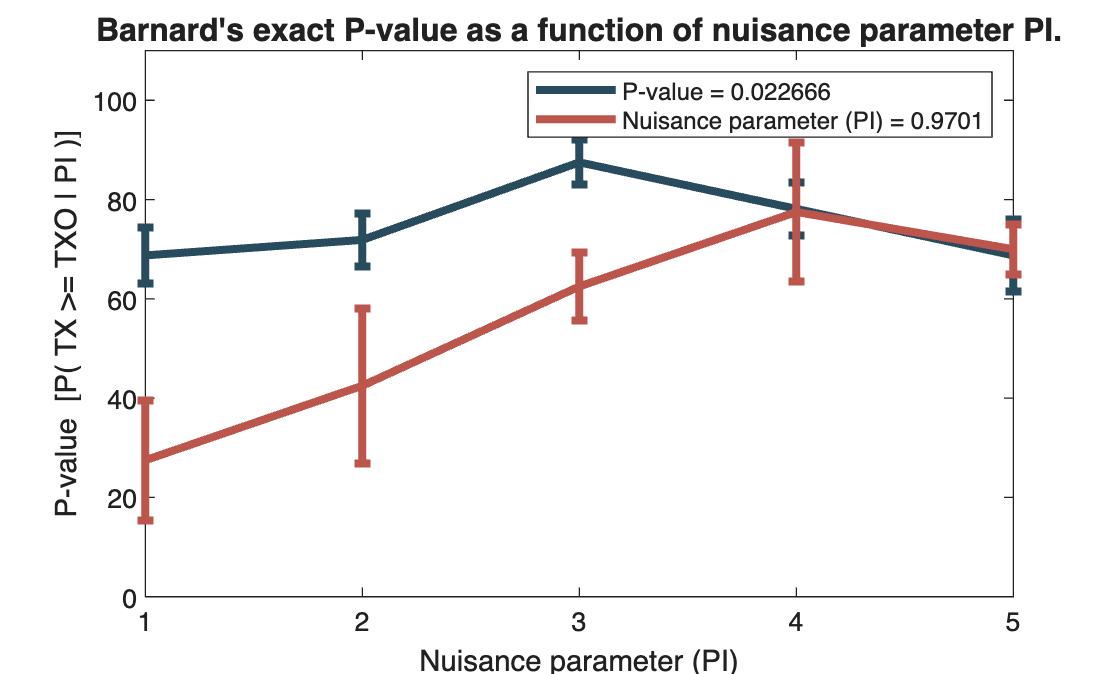

score_genotype = [mean(score_session(:,neg),2),mean(score_session(:,pos),2)];
score_genotype_se = [std(score_session(:,neg),0,2)/sqrt(length(score_session(:,neg))),std(score_session(:,pos),0,2)/sqrt(length(score_session(:,pos)))];

[~,p] = ttest2(score_session(:,neg)',score_session(:,pos)');

%test with Bernard's exact test assuming binomial distribution
% try a test assuming binomial distribution - Barnard's exact test
session1 = 1:8;
session2 = 9:16;
session3 = 17:24;
session4 = 25:23;
session5 = 24:40;

n_sucsess = sum(score_m(session3,neg),'all');
n_failure = 8*length(neg)-n_sucsess;
p_sucsess = sum(score_m(session3,pos),'all');
p_failure = 8*length(pos)-p_sucsess;

Barnardextest(n_sucsess,n_failure,p_sucsess,p_failure)

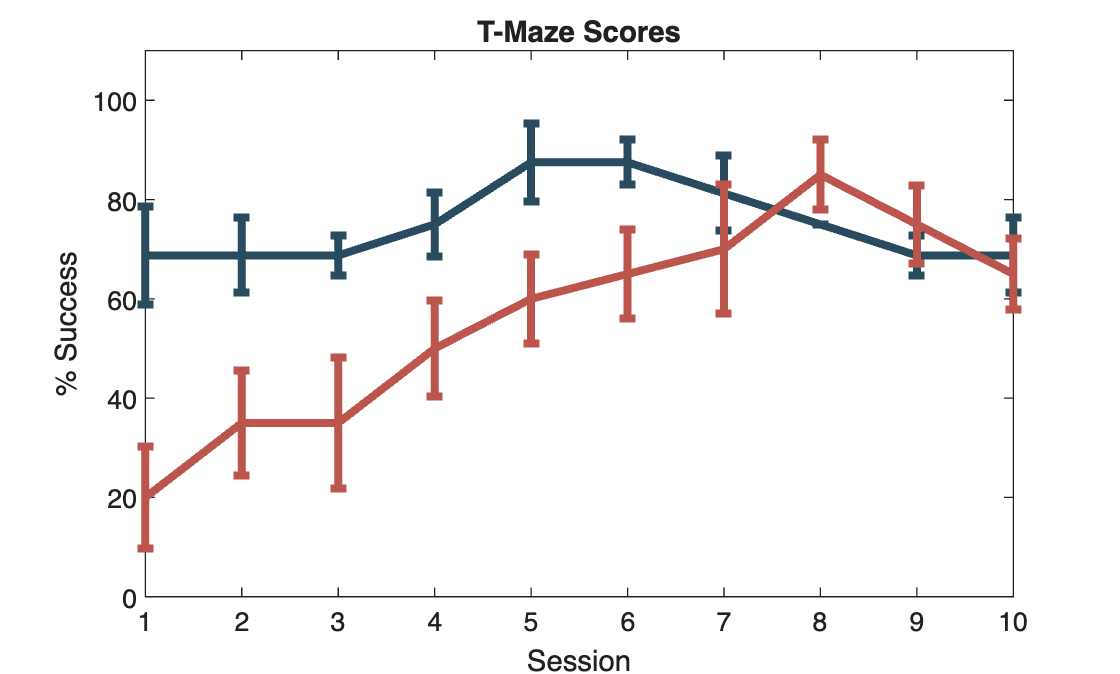


%Plot specifications
colors = {'#284B5E','#BC554C'};
noLine = {'none','none'};
linew = {3,3};

figure
c = plot(score_genotype,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Session');
ylabel('% Success');
ylim([0 100]);
er = errorbar(score_genotype,score_genotype_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('T-Maze Scores');
ylim([0 110]);
yticks(0:20:110);
xlim([1 10]);
xticks(1:1:10);

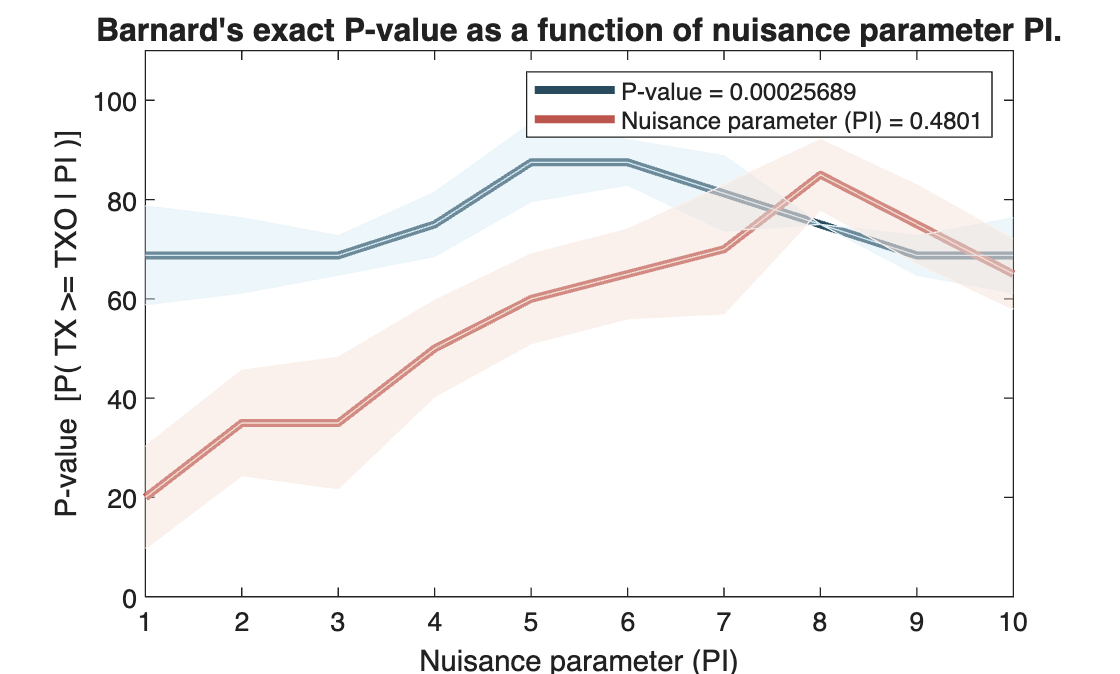

 
Table of the Barnard's exact test results for:
a = 22, b = 10, c = 11, d = 29
---------------------------------------------------
  Wald statistic     Nuisance parameter      P  
---------------------------------------------------
      3.4906               0.4801          0.0003
---------------------------------------------------
 
[Note:For a least conflict with figure, press the left mouse button on the legend and drag to the desired location.]



figure
c = plot(score_genotype,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Session');
ylabel('% Success');
ylim([0 100]);
shadedErrorBar(1:length(score_genotype(:,1)'),score_genotype(:,1)',score_genotype_se(:,1)','lineProps',{'color', [82.7, 91.4, 95.3]/100} ,'patchSaturation',0.4);
shadedErrorBar(1:length(score_genotype(:,2)'),score_genotype(:,2)',score_genotype_se(:,2)','lineProps',{'color', [95.3, 86.7, 82.7]/100} ,'patchSaturation',0.4);
[c(1).Color, c(2).Color] = colors{:};
title('T-Maze Scores');
ylim([0 110]);
yticks(0:20:110);
xlim([1 10]);
xticks(1:1:10);

gen_day = [mean(score_day(:,neg),2),mean(score_day(:,pos),2)];
gen_day_se = [std(score_day(:,neg),0,2)/sqrt(length(score_day(:,neg))),std(score_day(:,pos),0,2)/sqrt(length(score_day(:,pos)))];

[~,p1] = ttest2(score_day(:,neg)',score_day(:,pos)');

% try a test assuming binomial distribution - Barnard's exact test
day1 = 1:8;
day2 = 9:16;
day3 = 17:24;
day4 = 25:23;
day5 = 24:40;

n_sucsess = sum(score_m(day1,neg),'all');
n_failure = 8*length(neg)-n_sucsess;
p_sucsess = sum(score_m(day1,pos),'all');
p_failure = 8*length(pos)-p_sucsess;

%run for testing each day
Barnardextest(n_sucsess,n_failure,p_sucsess,p_failure);

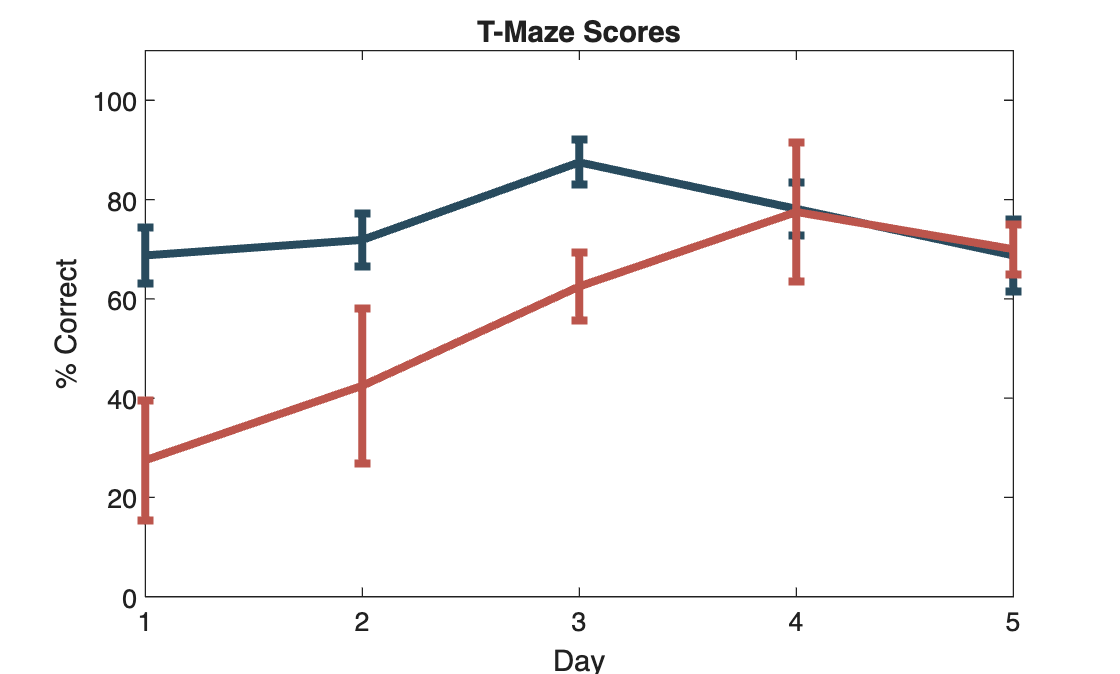


figure
c = plot(gen_day,'LineWidth',3);
hold on
[c(1).Color, c(2).Color] = colors{:};
xlabel('Day');
ylabel('% Correct');
ylim([0 100]);
er = errorbar(gen_day,gen_day_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('T-Maze Scores');
ylim([0 110]);
yticks(0:20:110);
xlim([1 5]);
xticks(1:1:5);

## Check the SAB

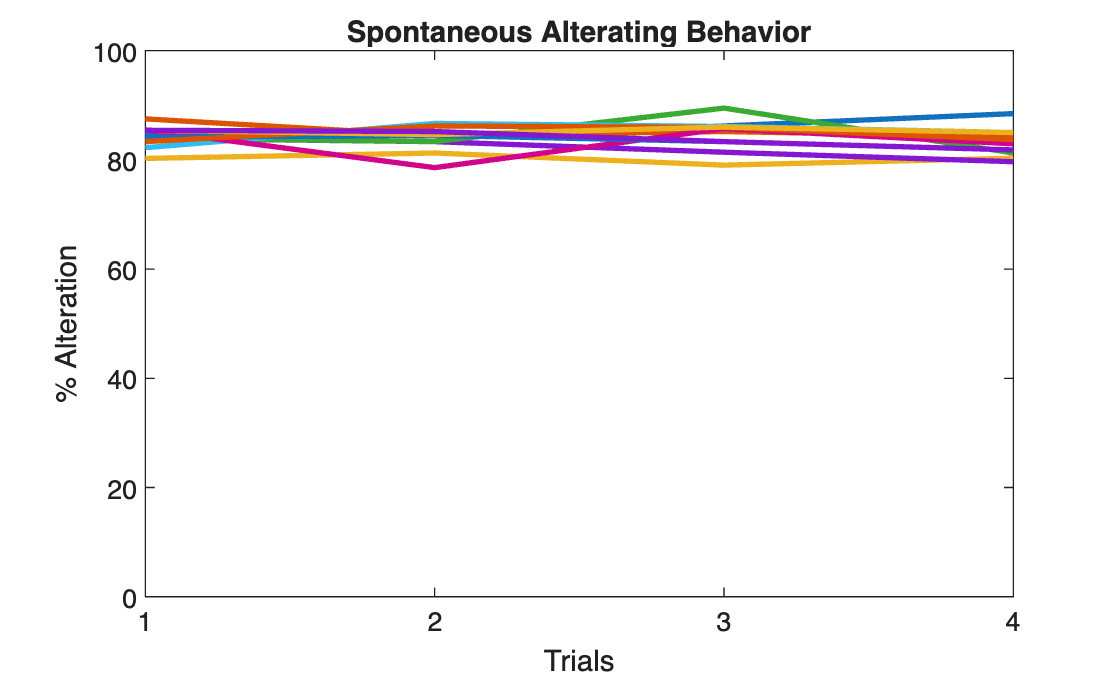

sab_score = SAB(all_entries(1:4,1:animals),animals,3).*100;

figure 
plot(sab_score,'LineWidth',2) 
ylim([0 100]);
title('Spontaneous Alterating Behavior');
ylabel('% Alteration');
ylim([0 100]);
yticks(0:20:100);
xlabel('Trials');
xlim([1 4]);
xticks(1:1:4);

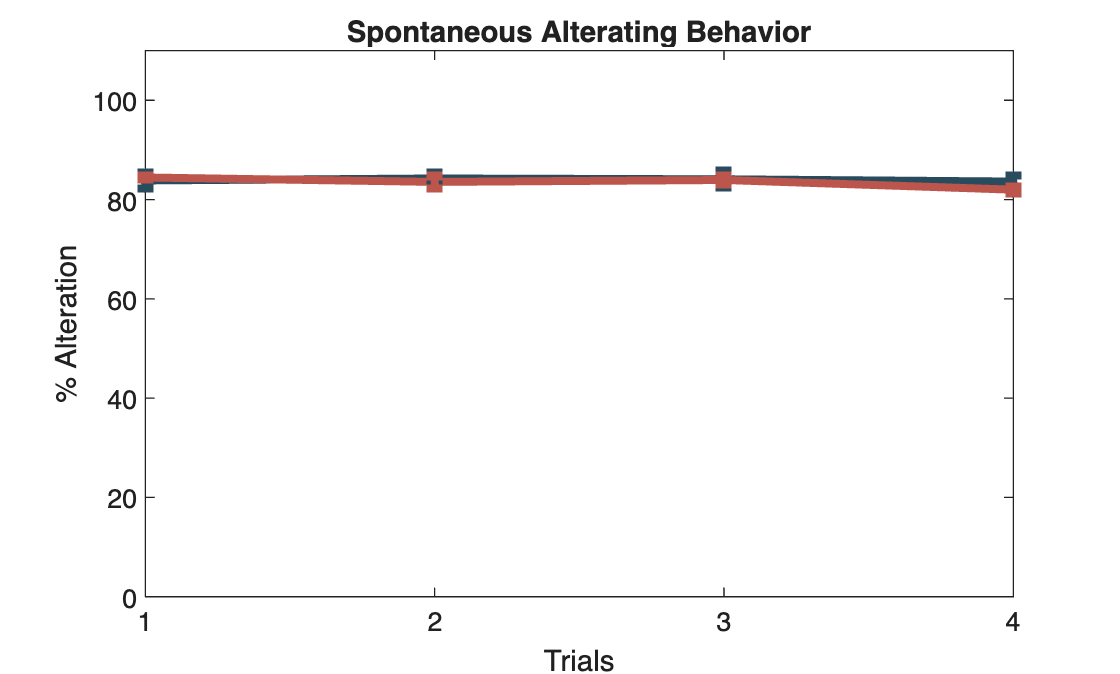


grouped_sab = [mean(sab_score(:,neg),2),mean(sab_score(:,pos),2)];
sab_se = [std(sab_score(:,neg),0,2)/sqrt(length(sab_score(:,neg))),std(sab_score(:,pos),0,2)/sqrt(length(sab_score(:,pos)))];


% test SAB difference
[~,p2] = ttest2(sab_score(:,neg)',sab_score(:,pos)'); %not sign

figure
c = plot(grouped_sab,'LineWidth',3);
hold on
ylim([0 100]);
er = errorbar(grouped_sab,sab_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('Spontaneous Alterating Behavior');
ylabel('% Alteration');
ylim([0 110]);
yticks(0:20:110);
xlabel('Trials');
xlim([1 4]);
xticks(1:1:4);

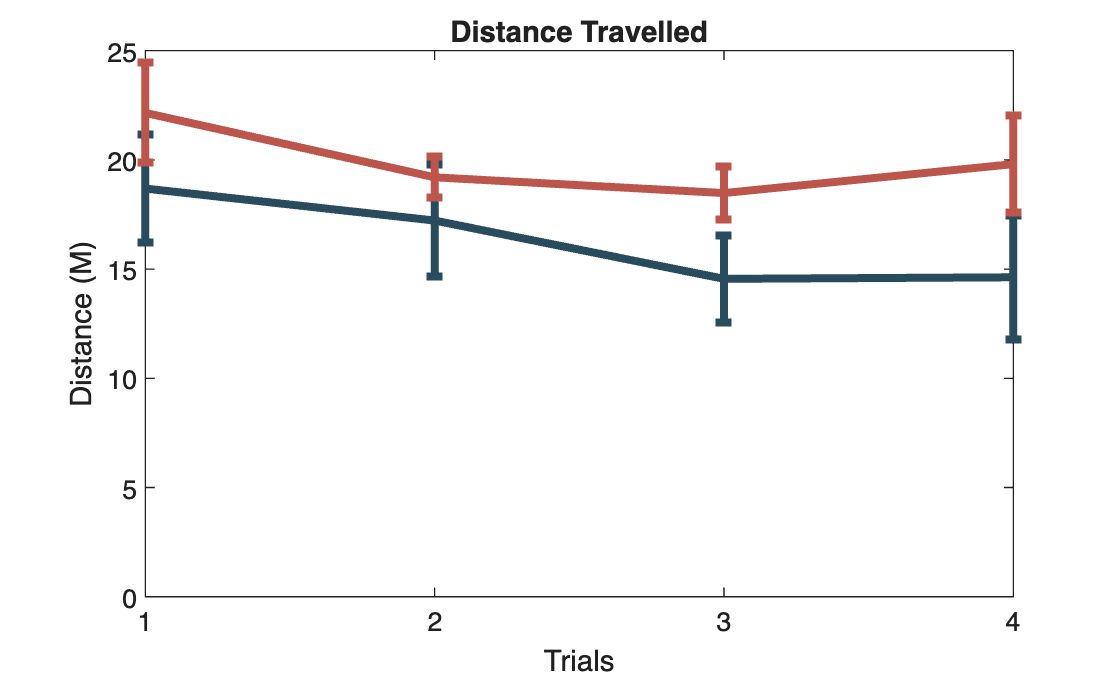



% Test distance travelled 
dt = distance_moved(1:4,:)./100;
dist = [mean(dt(:,neg),2),mean(dt(:,pos),2)];
dist_se = [std(dt(:,neg),0,2)/sqrt(length(dt(:,neg))),std(dt(:,pos),0,2)/sqrt(length(dt(:,pos)))];

% test difference in distance moved 
[~,p3] = ttest2(dt(:,neg)',dt(:,pos)'); %not sign

figure
c = plot(dist,'LineWidth',3);
hold on
% ylim([0 100]);
er = errorbar(dist,dist_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('Distance Travelled');
ylabel('Distance (M)');
ylim([0 25]);
yticks(0:5:25);
xlabel('Trials');
xlim([1 4]);
xticks(1:1:4);

## Speed

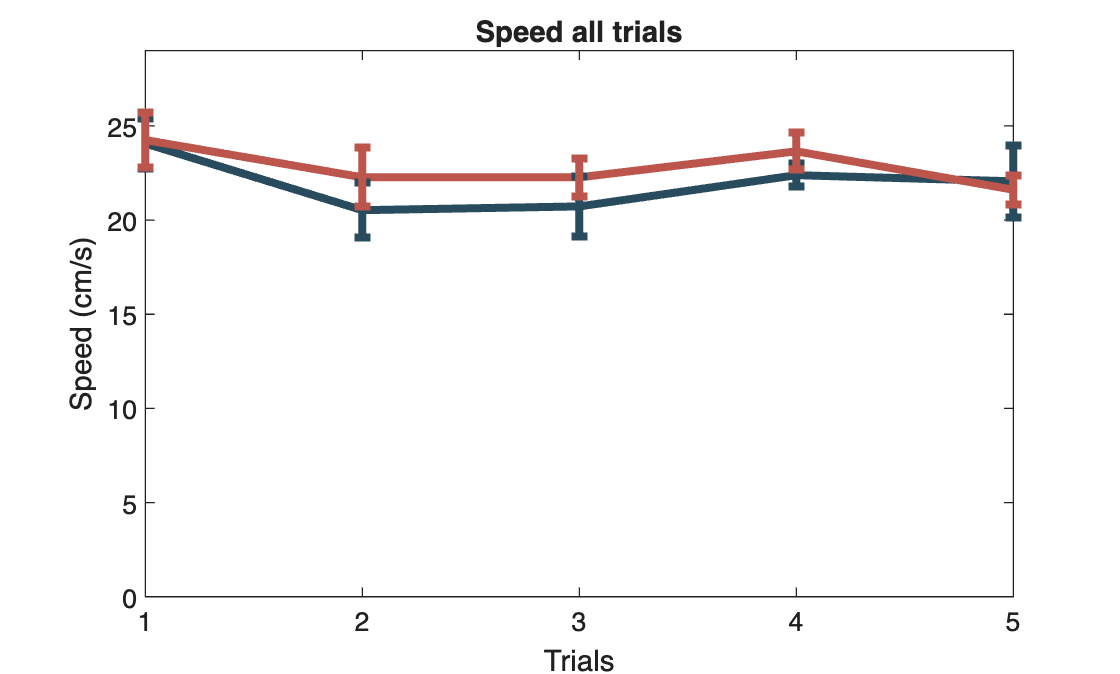

speed = speed(end-79:end,:);
speed_day = average_matrix(speed,animals,16);
[speed_gen,speed_se] = genotype(speed_day,neg,pos);

figure
c = plot(speed_gen,'LineWidth',3);
hold on
er = errorbar(speed_gen,speed_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('Speed all trials');
ylabel('Speed (cm/s)');
ylim([0 round(max(speed_gen,[],"all"))+5]);
xlabel('Trials');
xlim([1 5]);
xticks(1:1:5);

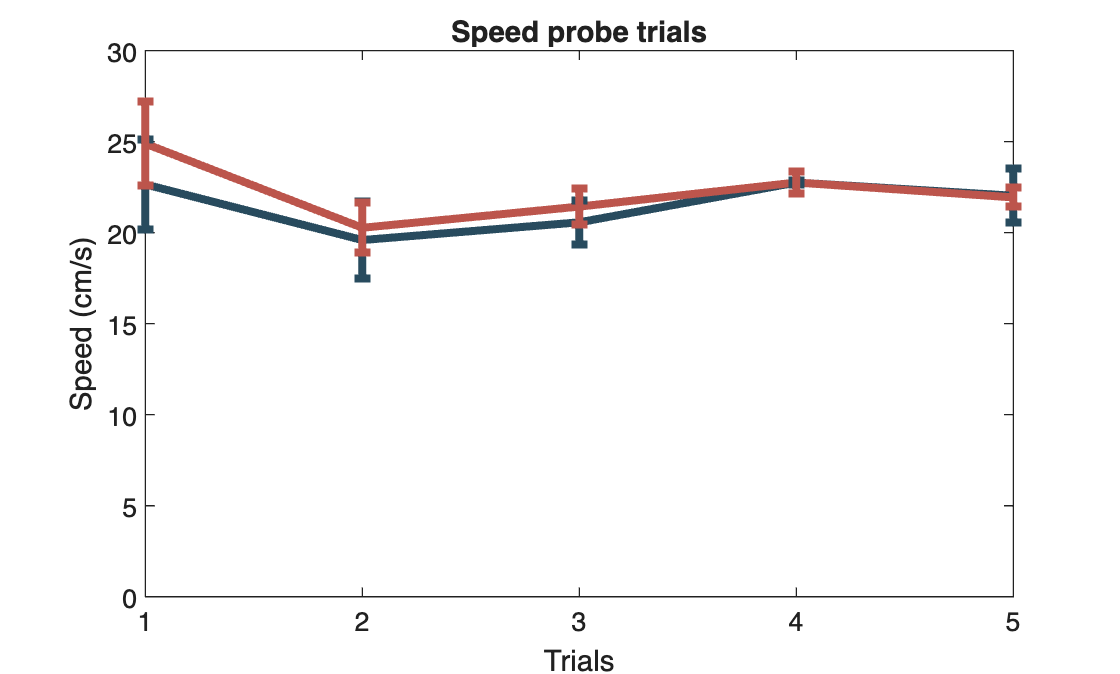


% separate the probe vs test trials
subsample_probe = speed(1:2:end,:);
subsample_test = speed(2:2:end,:); 


speed_test = average_matrix(subsample_probe,animals,8);
[speed_gen,speed_se] = genotype(speed_test,neg,pos);

figure
c = plot(speed_gen,'LineWidth',3);
hold on
er = errorbar(speed_gen,speed_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('Speed probe trials');
ylabel('Speed (cm/s)');
ylim([0 round(max(speed_gen,[],"all"))+5]);
xlabel('Trials');
xlim([1 5]);
xticks(1:1:5);

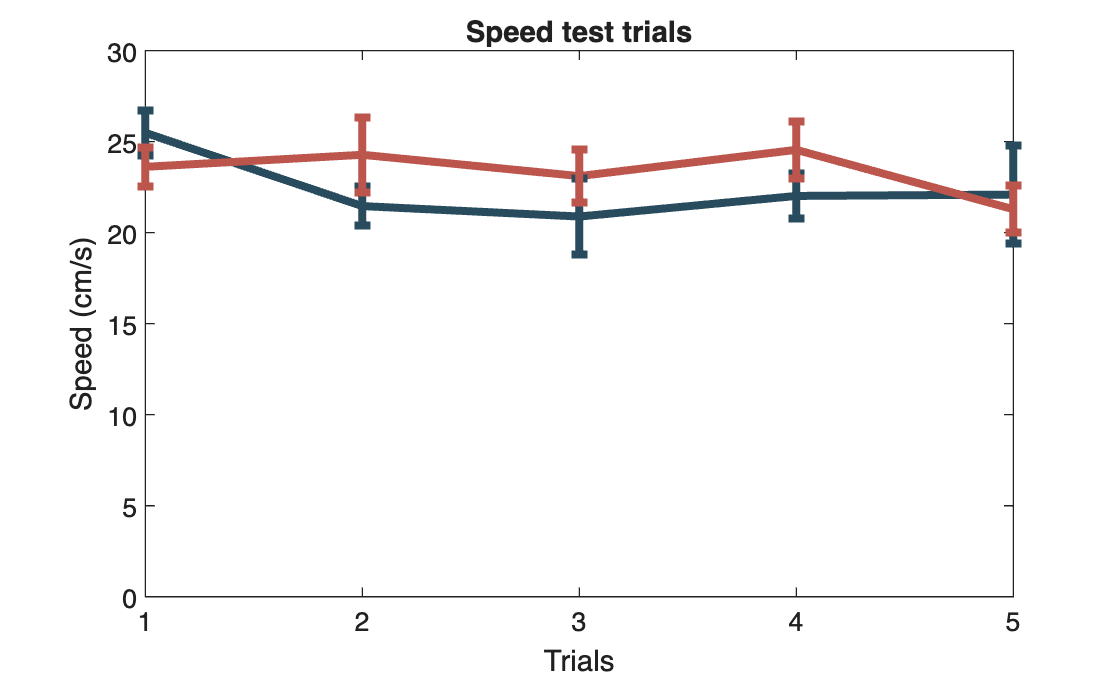


speed_test = average_matrix(subsample_test,animals,8);
[speed_gen,speed_se] = genotype(speed_test,neg,pos);

figure
c = plot(speed_gen,'LineWidth',3);
hold on
er = errorbar(speed_gen,speed_se);
[er(1).Color, er(2).Color] = colors{:};
[er(1).LineWidth, er(2).LineWidth] = linew{:};
[er(1).LineStyle, er(2).LineStyle] = noLine{:};
[c(1).Color, c(2).Color] = colors{:};
title('Speed test trials');
ylabel('Speed (cm/s)');
ylim([0 round(max(speed_gen,[],"all"))+5]);
xlabel('Trials');
xlim([1 5]);
xticks(1:1:5);